# Fourier Transform

- generate a multispectral signal with noise

sample_rate = 1024; %hz
N = sample_rate*2; %number of samples
t = (0:N-1)/sample_rate; %time vector

%create some random frequencies and amplitudes
freqs = [ floor(1+30*rand(3,1)')]; 
amplitudes = zeros(size(freqs));
signal = zeros(size(t));

for i=1:length(freqs)
    amplitudes(i) = randi(6);
    signal = signal + amplitudes(i)*sin(2*pi*freqs(i)*t);  %give some random amplitude
end

noisy = signal + randn(size(signal))*5;

- create strings for annotation

str1 = sprintf('freq: %d, amplitude: %d', freqs(1), amplitudes(1));
str2 = sprintf('freq: %d, amplitude: %d', freqs(2), amplitudes(2));
str3 = sprintf('freq: %d, amplitude: %d', freqs(3), amplitudes(3));

## Plot the true and noisy signals

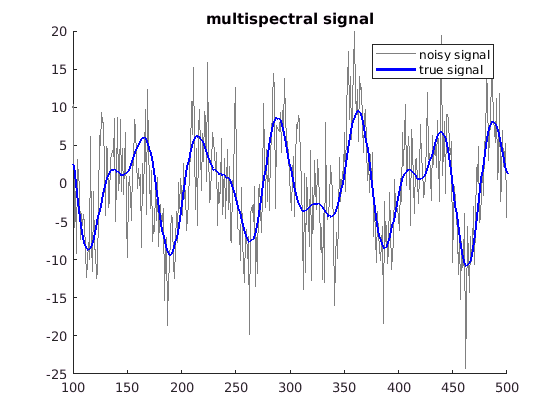

figure(1); clf;
hold on;
noisy_plot = plot(noisy);
set(noisy_plot, 'color', [.5 .5 .5]);
true_plot = plot(signal, 'b', 'linew', 2);
xlim([100 500]);
title("multispectral signal");
legend(["noisy signal", "true signal"]);
hold off;

## Apply FFT

signal_fft = fft(noisy);
signal_amp = 2*abs(signal_fft)/N;
hz_vals = linspace(0,sample_rate/2, floor(N/2)+1);

inv_signal = ifft(signal_fft); %apply inverse fft to reconstruct signal

## Plot the frequency spectrum

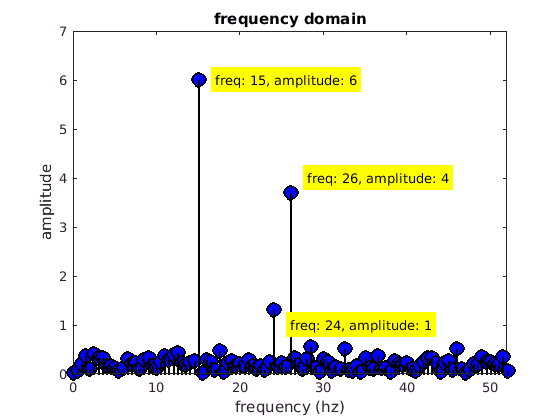

figure(2); clf;
stem(hz_vals, signal_amp(1:length(hz_vals)), 'ko', 'linew',2, 'markersize', 10, 'markerfacecolor', 'b');
set(gca, 'xlim', [0 max(freqs)*2]);
t1 = text(freqs(1)+2, amplitudes(1), str1, 'BackgroundColor', 'yellow');
t2 = text(freqs(2)+2, amplitudes(2), str2, 'BackgroundColor', 'yellow');
t3 = text(freqs(3)+2, amplitudes(3), str3, 'BackgroundColor', 'yellow');
xlabel("frequency (hz)");
ylabel("amplitude");
title("frequency domain");
hold off;

## Plot the inverse fft

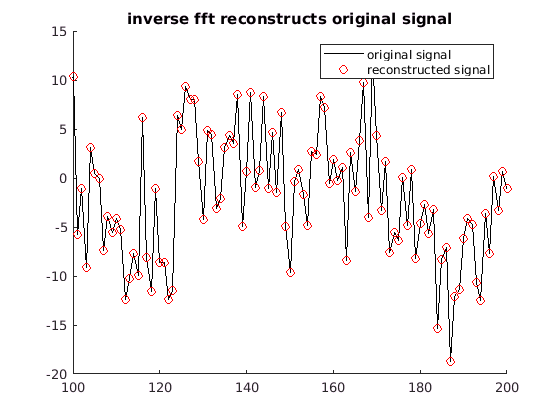

figure(3); clf;
hold on;
orig_plot = plot(noisy, 'k-');
inv_plot = plot(inv_signal, 'ro');
xlim([100 200]);
title("inverse fft reconstructs original signal");
legend(["original signal", "reconstructed signal"]);
hold off;

## Another Example

- normalized number of searches per week with term "signal processing"

clear all;
% data downloaded from https://trends.google.com/trends/explore?date=today%205-y&geo=US&q=signal%20processing
searches = [69 77 87 86 87 71 70 92 83 73 76 78 56 75 68 60 30 44 58 69 82 76 73 60 71 86 72 55 56 65 73 71 71 71 62 65 57 54 54 60 49 59 58 46 50 62 60 65 67 60 70 89 78 94 86 80 81 73 100 95 78 75 64 80 53 81 73 66 26 44 70 85 81 91 85 79 77 80 68 67 51 78 85 76 72 87 65 59 60 64 56 52 71 77 53 53 49 57 61 42 58 65 67 93 88 83 89 60 79 72 79 69 78 85 72 85 51 73 73 52 41 27 44 68 77 71 49 63 72 73 60 68 63 55 50 56 58 74 51 62 52 47 46 38 45 48 44 46 46 51 38 44 39 47 42 55 52 68 56 59 69 61 51 61 65 61 47 59 47 55 57 48 43 35 41 55 50 76 56 60 59 62 56 58 60 58 61 69 65 52 55 64 42 42 54 46 47 52 54 44 31 51 46 42 40 51 60 53 64 58 63 52 53 51 56 65 65 61 61 62 44 51 54 51 42 34 42 33 55 67 57 62 55 52 48 50 48 49 52 53 54 55 48 51 57 46 45 41 55 44 34 40 38 41 31 41 41 40 53 35 31];
N = length(searches);

%normalize the data
searches  = searches - mean(searches);

%square amplitude to get power
powers = abs(fft(searches)/N).^2;

%create freq bins
hz_vals = linspace(0,52,N);

- plot the search volume and power spectrum

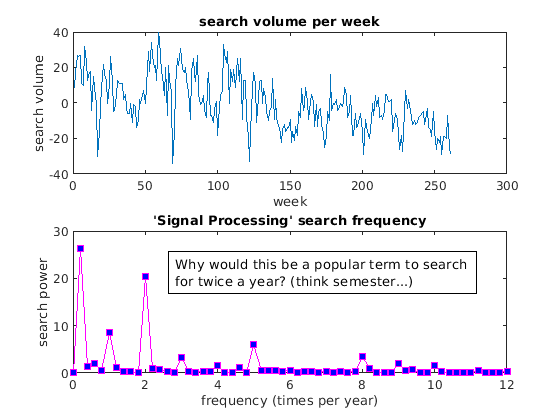

figure(4); clf;
subplot(211);
plot(searches);
title("search volume per week");
xlabel("week");
ylabel("search volume");

subplot(212);
plot(hz_vals, powers, 'ms-', 'markerfacecolor', 'b');
xlabel("frequency (times per year)");
ylabel("search power");
title("'Signal Processing' search frequency");
set(gca, 'xlim', [0 12]);
str = 'Why would this be a popular term to search for twice a year? (think semester...)';
annotation('textbox',[.3 .3 .55 .1],'String',str);

## Use windowing (welches method) to increase the signal to noise ratio

- [https://en.wikipedia.org/wiki/Welch%27s_method](https://en.wikipedia.org/wiki/Welch%27s_method) 

clear all;
load ../datasets/EEGrestingState.mat;
whos;

  Name         Size                 Bytes  Class     Attributes

  eegdata      1x122880            491520  single              
  srate        1x1                      8  double              



N = length(eegdata);
t = (0:N-1)/srate;
%get the power spectrum
powers = abs(fft(eegdata)/N).^2;
hz_vals = linspace(0, srate/2, floor(N/2)+1);

- Plot the data

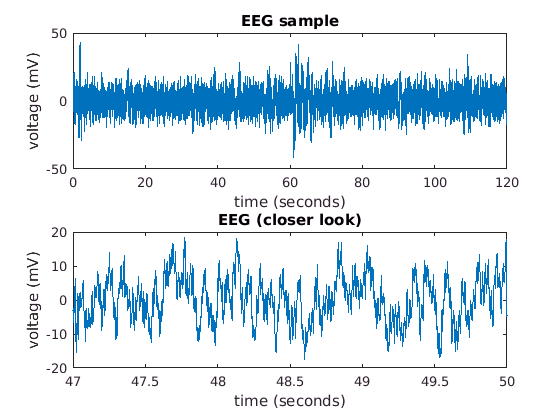

figure(5); clf;
subplot(211);
eeg_plot = plot(t, eegdata);
xlabel("time (seconds)");
ylabel("voltage (mV)");
title("EEG sample");

subplot(212);
eeg_plot = plot(t, eegdata);
xlim([47 50]);
xlabel("time (seconds)");
ylabel("voltage (mV)");
title("EEG (closer look)");

## Use Welches Method

- manaully first

- then us matlab function

- Hann window minimizes the edge effects

%window size is 1 sec, overlapping at .5 seconds
window_len = 1*srate; %seconds* sampling rate
%overlapping points in subsequent windows
num_overlap = round(srate/2); 
window_starts = 1:num_overlap:N-window_len;

window_hz = linspace(0, srate/2, floor(window_len/2)+1);
%https://en.wikipedia.org/wiki/Hann_function
window_hann = .5 - cos(2*pi*linspace(0,1,window_len))./2;
window_powers = zeros(1, length(window_hz));
%for plotting
samples = zeros(4, window_len);
j = 1;

for i=1:length(window_starts)
    piece = eegdata(window_starts(i):window_starts(i)+window_len-1);
    if i == 7 || i == 48
        samples(j,:) = piece;
        j = j + 1;
    end
    piece = piece .* window_hann;
    power = abs(fft(piece)/window_len).^2;
    window_powers = window_powers + power(1:length(window_hz));
    %get some samples to plot
    if i == 7 || i == 48
        samples(j,:) = piece;
        j = j + 1;
    end
end

window_powers = window_powers / (window_len * 2);

- Plot some sample windows

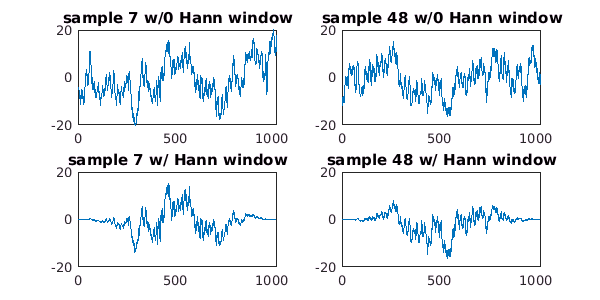

f6 = figure(6); clf;
f6.Position = [0,0,600,300];
subplot(221);
plot(samples(1,:));
title("sample 7 w/0 Hann window");
xlim([0 1024]); ylim([-20 20]);

subplot(223);
plot(samples(2,:));
title("sample 7 w/ Hann window");
xlim([0 1024]); ylim([-20 20]);

subplot(222);
plot(samples(3,:));
title("sample 48 w/0 Hann window");
xlim([0 1024]); ylim([-20 20]);

subplot(224);
plot(samples(4,:));
title("sample 48 w/ Hann window");
xlim([0 1024]); ylim([-20 20]);

- Plot the power spectrum of welches method

- compare to normal

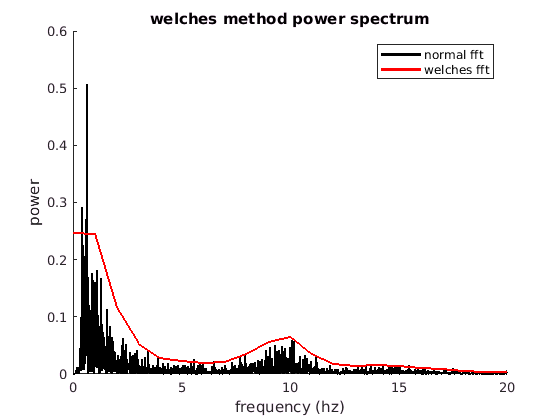

figure(7); clf;
hold on;
plot(hz_vals, powers(1:length(hz_vals)), 'k', 'linew', 2);
plot(window_hz, window_powers, 'r', 'linew', 2);
xlim([0 20]);
title("welches method power spectrum");
xlabel("frequency (hz)");
ylabel("power");
legend(["normal fft", "welches fft"]);

- use matlab function

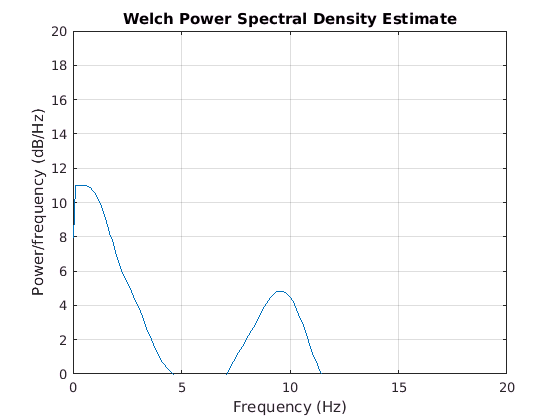

figure(8); clf;
pwelch(eegdata, window_hann, round(window_len/4), srate*10, srate);
xlim([0 20]);
ylim([0 20]);